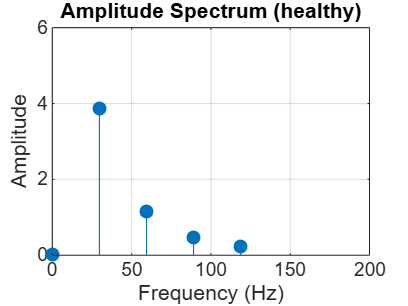


data= readtable('r4b_test_8pt.xlsx');
vibData = data.Vib_base;

Fs = 7600/32;
N = 8;

X = fft(vibData,N); % N point DFT
f = (0:N-1)*(Fs/N);

P1 = abs(X(1:floor(N/2)+1))/(N+4);
f1 = f(1:floor(N/2)+1);

figure;
stem(f1, P1, "filled")
axis([0 200 0 6])
xlabel('Frequency (Hz)')
ylabel('Amplitude')
title('Amplitude Spectrum ')
grid on;